
RGB=imread("..\img\pzl_4_4.jpg");
I = rgb2gray(RGB);
gmag = imgradient(I);
imshow(gmag,[])
title('Gradient Magnitude')
se = strel('disk',20);
Io = imopen(I,se);

imshow(Io)
title('Opening')
Ie = imerode(I,se);
Iobr = imreconstruct(Ie,I);
imshow(Iobr)
title('Opening-by-Reconstruction')
Ioc = imclose(Io,se);
imshow(Ioc)
title('Opening-Closing')

Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr)
imshow(imgradient(Iobrcbr))
imshow(imsegkmeans(Iobrcbr,2),[])

title('Opening-Closing by Reconstruction')
fgm = imregionalmax(Iobrcbr);
imshow(fgm)
title('Regional Maxima of Opening-Closing by Reconstruction')
se2 = strel(ones(5,5));
fgm2 = imclose(fgm,se2);
fgm3 = imerode(fgm2,se2);
fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(I,fgm4);
imshow(I3)
title('Modified Regional Maxima Superimposed on Original Image')
bw = imbinarize(Iobrcbr);
imshow(bw)
title('Thresholded Opening-Closing by Reconstruction')
D = bwdist(bw);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title('Watershed Ridge Lines')

open checkerboardPattern.pdf

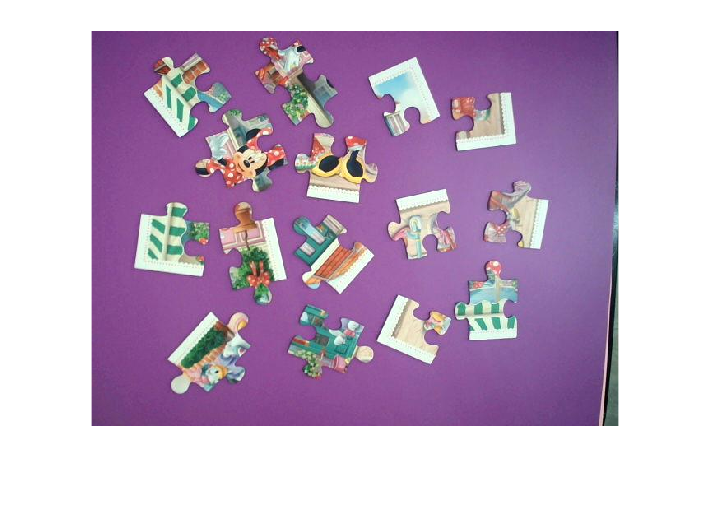

N=15;
num_row = 3;
num_col = 5;
%grid
RGB_grid = imread("DIP_Puzzle_Solver\img\pzl_15_p3.jpg");
% img_grid = grid_puzzle(RGB_grid,N);
img_grid=RGB_grid;
RGB = imread(strcat("DIP_Puzzle_Solver\img\temp_tests\15_pzl_webcam_test.jpg"));
% image
figure;
imshow(RGB)

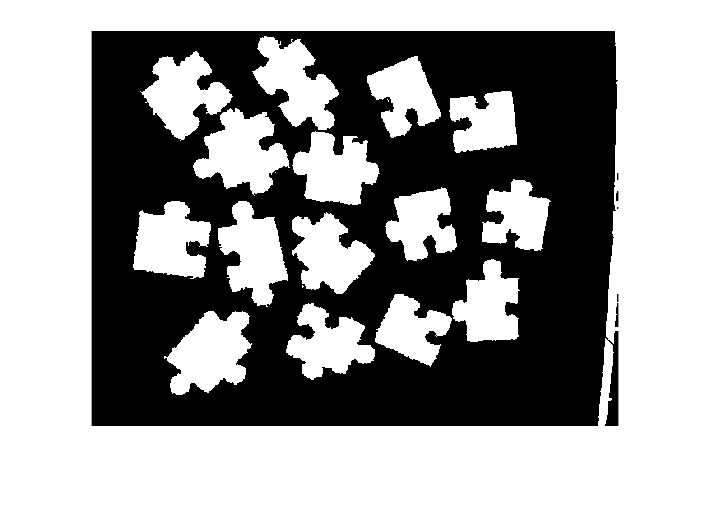

ImgGray = double(rgb2gray(RGB));
I = (ImgGray - min(ImgGray(:)))/(max(ImgGray(:)) - min(ImgGray(:)));

%segmentation
tic;
[a,c]=segmentation(I,1,2,0.7,20);

toc;

Elapsed time is 0.349708 seconds.


figure;
imshow(a);

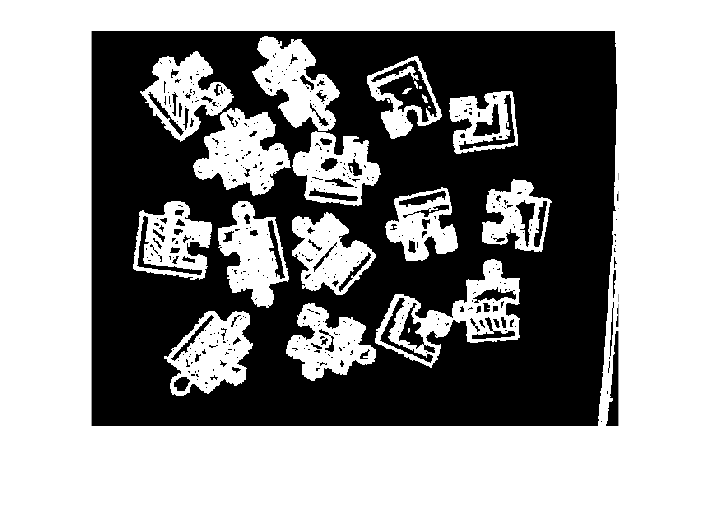

figure;
imshow(c);


% cut image
tic;
imgCell = cut_images(RGB,a,N,10);
toc;

Elapsed time is 0.112860 seconds.



% match features
rel_vec = zeros(N,1);
f2=0;
vpts2=0;
for i = 1:N
    piece = imgCell{i};
    piece = imresize(piece,8);
    [location,reliability,f2,vpts2] = matching_features(piece,img_grid,num_row,num_col,0,f2,vpts2);
    rel_vec(i) = reliability;
    fprintf("The location for piece #%d is (%d,%d), reliability = %4f\n" ...
        ,i,location(1),location(2),reliability);
end

Elapsed time is 0.447175 seconds.
Elapsed time is 0.260323 seconds.


The location for piece #1 is (1,1), reliability = 0.545215


Elapsed time is 0.428825 seconds.
Elapsed time is 0.379224 seconds.


The location for piece #2 is (3,1), reliability = 0.449345


Elapsed time is 0.496989 seconds.
Elapsed time is 0.356287 seconds.


The location for piece #3 is (5,2), reliability = 0.582494


Elapsed time is 0.412728 seconds.
Elapsed time is 0.430707 seconds.


The location for piece #4 is (2,2), reliability = 0.649454


Elapsed time is 0.430343 seconds.
Elapsed time is 0.311026 seconds.


The location for piece #5 is (1,2), reliability = 0.702697


Elapsed time is 0.418889 seconds.
Elapsed time is 0.384317 seconds.


The location for piece #6 is (3,2), reliability = 0.688890


Elapsed time is 0.395740 seconds.
Elapsed time is 0.314349 seconds.


The location for piece #7 is (4,2), reliability = 0.495950


Elapsed time is 0.416462 seconds.
Elapsed time is 0.380517 seconds.


The location for piece #8 is (4,1), reliability = 0.409616


Elapsed time is 0.435372 seconds.
Elapsed time is 0.316337 seconds.


The location for piece #9 is (2,3), reliability = 0.552063


Elapsed time is 0.444289 seconds.
Elapsed time is 0.249795 seconds.


The location for piece #10 is (3,3), reliability = 0.201144


Elapsed time is 0.427310 seconds.
Elapsed time is 0.256241 seconds.


The location for piece #11 is (2,2), reliability = 0.217515


Elapsed time is 0.415731 seconds.
Elapsed time is 0.251036 seconds.


The location for piece #12 is (4,3), reliability = 0.419560


Elapsed time is 0.420508 seconds.
Elapsed time is 0.182649 seconds.


The location for piece #13 is (1,3), reliability = 0.502860


Elapsed time is 0.443248 seconds.
Elapsed time is 0.265542 seconds.


The location for piece #14 is (2,1), reliability = 0.517317


Elapsed time is 0.402927 seconds.
Elapsed time is 0.212393 seconds.


The location for piece #15 is (3,3), reliability = 0.342886


disp(mean(rel_vec));

    0.4851



% figure;
% for i=1:N
%     subplot(6,4,i);
%     imshow(imgCell{i});
% end

clc
clear
close all

img=imread("img\temp_tests\15_pzl_webcam_test.jpg");
img_grid=imread("img\pzl_15_p3.jpg");
num_of_pieces=15;
num_row=3;
num_col=5;
dialtion_size1=1;
dialation_size2=5;
extent_filter=0.6;
center_size=10;
resize_factor=8;
show=false;

%noremelized and grayScale the images:

gray_grid = double(im2gray(img_grid));
gray_grid = (gray_grid - min(gray_grid(:)))/(max(gray_grid(:)) - min(gray_grid(:)));
if show
    figure
    imshow(gray_grid)
end
gray_img= double(im2gray(img));
gray_img = (gray_img- min(gray_img(:)))/(max(gray_img(:)) - min(gray_img(:)));
[seg_img,puz_edges] = segmentation(gray_img,dialtion_size1,dialation_size2,extent_filter,center_size);
imgCell = cut_images(img,seg_img,num_of_pieces,10);
%% features:
location_matrix_features=cell(num_row,num_col);
reliability_matrix_features=cell(num_row,num_col);
%% histograms
location_matrix_hist=cell(num_row,num_col);
reliability_matrix_hist=(cell(num_row,num_col));
%% 
location_matrix_shape=cell(num_row,num_col);
% piece = imgCell{9};
% piece=imresize(piece,resize_factor);
% A=4;
format default;
format compact;
flag = 0;
tic;
f2=0;
vpts2=0;
sumrel=0;
for i =1:num_of_pieces
    piece = imgCell{i};
%     piece_mem = piece;
%     piece = imgaussfilt(piece,30);
%     piece(piece_mem~=0) = piece_mem(piece_mem~=0);
    piece=imresize(piece,resize_factor);
    
%     piece(piece==0) = 255;
    if (show)
        figure
        imshow(piece)
    end
%     figure;
%     imshow(piece);
%     figure;

    [location_features,reliability_features,f2,vpts2] = matching_features(piece,img_grid,num_row,num_col,flag,0,f2,vpts2);
%     [puzzel_shape loc_mat]=detect_pazzel_shape(piece,resize_factor)

    % fprintf("The location for piece #%d is (%d,%d), reliability = %4f\n" ...
    %     ,i,location(1),location(2),reliability);
    location_matrix_features{location_features(2),location_features(1)}=[location_matrix_features{location_features(2),location_features(1)},i];
    reliability_matrix_features{location_features(2),location_features(1)}=[reliability_matrix_features{location_features(2),location_features(1)},reliability_features];
%     location_matrix_shape{location_features(2),location_features(1)}=[location_matrix_shape{location_features(2),location_features(1)},puzzel_shape];
%     [location_hist,reliability_hist] = compere_histograms(piece,img_grid,num_row,num_col,show);
%     location_matrix_hist{location_hist(1),location_hist(2)}=[location_matrix_hist{location_hist(1),location_hist(2)},i];
%     reliability_matrix_hist{location_hist(1),location_hist(2)}=[reliability_matrix_hist{location_hist(1),location_hist(2)},reliability_hist];
    sumrel = sumrel+reliability_features;
end

Elapsed time is 0.193986 seconds.
Elapsed time is 0.327265 seconds.
Elapsed time is 0.253894 seconds.
Elapsed time is 0.349092 seconds.
Elapsed time is 0.273550 seconds.
Elapsed time is 0.326634 seconds.
Elapsed time is 0.253098 seconds.
Elapsed time is 0.265927 seconds.
Elapsed time is 0.258069 seconds.
Elapsed time is 0.205410 seconds.
Elapsed time is 0.204038 seconds.
Elapsed time is 0.211859 seconds.
Elapsed time is 0.132704 seconds.
Elapsed time is 0.160468 seconds.
Elapsed time is 0.176608 seconds.


toc;

Elapsed time is 0.202403 seconds.


(location_matrix_features)

location_matrix_features = 3×5 cell array
    {[ 1]}    {[14]}    {[ 2]}    {[ 9]}    {[10]}
    {[ 5]}    {[ 4]}    {[ 6]}    {[ 7]}    {[ 3]}
    {[13]}    {[ 8]}    {[15]}    {[12]}    {[11]}

(location_matrix_shape)

location_matrix_shape = 3×5 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}



(reliability_matrix_features)

reliability_matrix_features = 3×5 cell array
    {[0.7862]}    {[0.6205]}    {[0.5496]}    {[0.5009]}    {[0.4429]}
    {[0.7967]}    {[0.7681]}    {[0.7741]}    {[0.6524]}    {[0.8165]}
    {[0.5797]}    {[0.2828]}    {[0.4753]}    {[0.4618]}    {[0.3024]}

sumrel/num_of_pieces

ans = 0.5873

% (reliability_matrix_hist)

N=15;
RGB=imread("..\img\test_15_1.jpeg");
figure;
imshow(RGB)
% RGB = imread('kobi.png');
% RGB=imresize(RGB,0.1);

img=dip_GN_imread("..\img\test_15_1.jpeg");
% BW=edge(img,"prewitt");
tic;
BW= imgradient(img)>0.2;
% imshow(BW);
% imshow(imclose(BW,strel("rectangle",[2,2])));

dial = imdilate(BW,strel("rectangle",[2,2]));
% se = strel('disk',20);
% Iobrd = imdilate(BW,se);
% Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(BW));
% Iobrcbr = imcomplement(Iobrcbr);
% imshow(Iobrcbr)
% solidity = bwpropfilt(dial, 'Solidity', [0, 0.5]);
extent = bwpropfilt(dial, 'Extent', [0, 0.3]);
% area_filter = bwpropfilt(dial, 'Area', [1000, 65633]);
% imshow(BW);
% imshow(dial);
% imshow(solidity);
% imshow(extent);
% imshow(imdilate(extent,strel("rectangle",[7,7])));
ext_dial = imdilate(extent,strel("rectangle",[5,5]));


% imshow(area_filter);
% imshow(imfill(area_filter,"holes"));
% imshow(imfill(area_filter,8,"holes"));
% imshow(imfill(extent,"holes"));
% imshow(imfill(imfill(solidity,'holes'),"holes"));
% I = im2gray(im2single(RGB));
% evolved = activecontour(I,ext_dial,10,"Chan-vese","ContractionBias",-0.1);
mask = imfill(double(ext_dial),8,"holes");
% toc;
% tic;
% mask = imerode(mask,strel("rectangle",[10,10]));
% mask2 = imerode(mask,strel("rectangle",[100,100]));
% imshow(mask);
% imshow(bwareafilt(logical(mask),N));
% imshow(labled==6);
% imshow(labled);
% imshow(labeloverlay(RGB,mask));
% maskOpen = ~bwareaopen(~mask, 10);
distTrans = -bwdist(~mask);
% toc;
% imshow(maskOpen);
% imshow(distTrans,[]);
% Ld = watershed(distTrans);
% imshow(label2rgb(Ld))
% bw2 = mask;
% bw2(Ld == 0) = 0;
% imshow(bw2);
% tic;
extended_dist = imextendedmin(distTrans,60);
% toc;
% imshow(extended_dist);
% tic;
% imshowpair(mask,extended_dist,'blend');
D2 = imimposemin(distTrans,extended_dist);
% toc;
% tic;
Ld2 = watershed(D2);
% toc;
% tic;
bw3 = mask;
bw3(Ld2 == 0) = 0;
% imshow(bw3);
% toc;
% tic;
C = cut_images(RGB,bw3,N,50);
toc;
figure;
for i=1:N
    subplot(5,3,i);
    imshow(C{i});
end
% labled = bwlabel(bwareafilt(logical(mask),4));
% imshow(bwareafilt(logical(mask),4));
% extra_space = 50;
% imgCell = cell(N);
% for i=1:N
%     temp = labled==i;
%     [r,c]=find(labled==i);
%     
%     temp2 = RGB.*cast(temp,"like",RGB);
%     r_low = max(min(r)-extra_space,0);
%     r_high = min(max(r)+extra_space,size(temp,1));
%     c_low = max(min(c)-extra_space,0);
%     c_high = min(max(c)+extra_space,size(temp,2));
%     img_cut=temp2(r_low:r_high,c_low:c_high,:);
%     mask_cut = temp(r_low:r_high,c_low:c_high);
%     
%     BWedge = edge(mask_cut,"prewitt");
%     [H,T,R] = hough(BWedge);
%     peaks = houghpeaks(H,N*4);
%     lines = houghlines(BWedge,T,R,peaks);
%     angles = [lines.theta]';
%     [~,two_angles,~,~] = kmeans(angles,2);
%     a1 = mod(two_angles(1),90);
%     if (a1>45)
%         a1 = a1-90;
%     end
%     img_rot = imrotate(img_cut,a1,"crop");
%     cell{i} = img_rot;
%     subplot(2,2,i);
%     imshow(cell{i});
% %     hold on
% %     max_len = 0;
% %     for k = 1:length(lines)
% %        xy = [lines(k).point1; lines(k).point2];
% %        plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
% %     
% %        % Plot beginnings and ends of lines
% %        plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
% %        plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
% %     
% %        % Determine the endpoints of the longest line segment
% %        len = norm(lines(k).point1 - lines(k).point2);
% %        if ( len > max_len)
% %           max_len = len;
% %           xy_long = xy;
% %        end
% %     end
%     
% end
% filled = imfill(evolved,"holes");
% imshow(evolved);
% imshow(filled);
% C = labeloverlay(RGB,filled);
% imshow(C)
% nrows = size(RGB,1);
% ncols = size(RGB,2);
% [X,Y] = meshgrid(1:ncols,1:nrows);
% I = im2gray(im2single(RGB));
% imshow(I);
% imshow(I-extent*0.5);
% featureSet = cat(3,I,X,Y,extent);
% uint8(V*255)
% L2 = imsegkmeans(I-extent*0.5,2,'NormalizeInput',true);
% C = labeloverlay(RGB,imfill(L2,"holes"));
% imshow(C)

thresh = uint8(3);
thresh2 = uint8(3);
a=fill_black(BW,2,thresh);
b = fill_white(a,3,thresh2);
imshow(a);
imshow(b);
imshow(BW);

% [H, S ,V]=rgb2hsv(RGB);
% S=uint8(S);
% L = imsegkmeans(S,2);
% B = labeloverlay(S,L);
% imshow(B)
% title('Labeled Image')



% wavelength = 2.^(0:5) * 3;
% orientation = 0:45:135;
% g = gabor(wavelength,orientation);
% 
% I = im2gray(im2single(RGB));
% gabormag = imgaborfilt(I,g);

montage(gabormag,'Size',[4 6])

nrows = size(RGB,1);
ncols = size(RGB,2);
[X,Y] = meshgrid(1:ncols,1:nrows);
% featureSet = cat(3,I,gabormag,X,Y,BW);
RGB=imread("..\img\pzl_4_2.jpg");
contrasted = histeq(RGB,64);
imshow(contrasted);
[H, S ,V]=rgb2hsv(contrasted);
featureSet = cat(3,uint8(V*255),uint8(H*255));
% uint8(V*255)
L2 = imsegkmeans(uint8(V*255),2,'NormalizeInput',true);
C = labeloverlay(RGB,L2);
imshow(C)
title('Labeled Image with Additional Pixel Information')

RGB=imread("..\img\pzl_6_2.jpg");
imshow(autosegmentImage(RGB));